# 清空数据

clc 
clear

## 初始化网格

global Nx Ny; %#ok<GVMIS>
Nx = 200; Ny = 200;
mesh = ConstuctMesh([Nx,Ny],[1,1]);

## 初始化时间控制

dt = 1;
ntimeStep = 100;
t = time(dt,ntimeStep);

## 初始化物理参数

k = 10;

## 初始化物理场

T = generatefield(mesh,fieldDimension.vol,fieldType.scalar);

## 物理场赋值

T = initialFieldValue(T,0);

## 初始化边界条件

T = setBoundaryCondition(T,1,BCType.Dirichlet,BCSelect.w);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.e);
T = setBoundaryCondition(T,0,BCType.Dirichlet,BCSelect.s);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.n);

## 矩阵组装和求解

while t.loop(t)
    tic
    ddt_T = ddt_fvm(mesh,t,ddtScheme.Euler,T,1000);
    lap_T = laplace_fvm(mesh,k,laplaceScheme.Gauss,T);
    [Matrix_T,T] = matrixSystem(T,[ddt_T,lap_T],['+','-'],IS.solve);
    toc
end

时间循环开始：
当前时间为0,下一时间为1。


历时 0.102315 秒。


当前时间为1,下一时间为2。


历时 0.098449 秒。


当前时间为2,下一时间为3。


历时 0.084660 秒。


当前时间为3,下一时间为4。


历时 0.110081 秒。


当前时间为4,下一时间为5。


历时 0.095628 秒。


当前时间为5,下一时间为6。


历时 0.101877 秒。


当前时间为6,下一时间为7。


历时 0.125009 秒。


当前时间为7,下一时间为8。


历时 0.096981 秒。


当前时间为8,下一时间为9。


历时 0.092367 秒。


当前时间为9,下一时间为10。


历时 0.083861 秒。


当前时间为10,下一时间为11。


历时 0.096963 秒。


当前时间为11,下一时间为12。


历时 0.097384 秒。


当前时间为12,下一时间为13。


历时 0.112262 秒。


当前时间为13,下一时间为14。


历时 0.108720 秒。


当前时间为14,下一时间为15。


历时 0.103907 秒。


当前时间为15,下一时间为16。


历时 0.099822 秒。


当前时间为16,下一时间为17。


历时 0.098918 秒。


当前时间为17,下一时间为18。


历时 0.087838 秒。


当前时间为18,下一时间为19。


历时 0.094343 秒。


当前时间为19,下一时间为20。


历时 0.117944 秒。


当前时间为20,下一时间为21。


历时 0.097423 秒。


当前时间为21,下一时间为22。


历时 0.104474 秒。


当前时间为22,下一时间为23。


历时 0.098843 秒。


当前时间为23,下一时间为24。


历时 0.102067 秒。


当前时间为24,下一时间为25。


历时 0.124571 秒。


当前时间为25,下一时间为26。


历时 0.115598 秒。


当前时间为26,下一时间为27。


历时 0.104308 秒。


当前时间为27,下一时间为28。


历时 0.120486 秒。


当前时间为28,下一时间为29。


历时 0.104888 秒。


当前时间为29,下一时间为30。


历时 0.116295 秒。


当前时间为30,下一时间为31。


历时 0.102589 秒。


当前时间为31,下一时间为32。


历时 0.104915 秒。


当前时间为32,下一时间为33。


历时 0.098985 秒。


当前时间为33,下一时间为34。


历时 0.109232 秒。


当前时间为34,下一时间为35。


历时 0.113954 秒。


当前时间为35,下一时间为36。


历时 0.101733 秒。


当前时间为36,下一时间为37。


历时 0.099874 秒。


当前时间为37,下一时间为38。


历时 0.102888 秒。


当前时间为38,下一时间为39。


历时 0.102871 秒。


当前时间为39,下一时间为40。


历时 0.123691 秒。


当前时间为40,下一时间为41。


历时 0.102349 秒。


当前时间为41,下一时间为42。


历时 0.094102 秒。


当前时间为42,下一时间为43。


历时 0.105906 秒。


当前时间为43,下一时间为44。


历时 0.127833 秒。


当前时间为44,下一时间为45。


历时 0.126492 秒。


当前时间为45,下一时间为46。


历时 0.104996 秒。


当前时间为46,下一时间为47。


历时 0.103839 秒。


当前时间为47,下一时间为48。


历时 0.101144 秒。


当前时间为48,下一时间为49。


历时 0.106525 秒。


当前时间为49,下一时间为50。


历时 0.111970 秒。


当前时间为50,下一时间为51。


历时 0.096599 秒。


当前时间为51,下一时间为52。


历时 0.115823 秒。


当前时间为52,下一时间为53。


历时 0.083095 秒。


当前时间为53,下一时间为54。


历时 0.096199 秒。


当前时间为54,下一时间为55。


历时 0.090032 秒。


当前时间为55,下一时间为56。


历时 0.081804 秒。


当前时间为56,下一时间为57。


历时 0.092314 秒。


当前时间为57,下一时间为58。


历时 0.108397 秒。


当前时间为58,下一时间为59。


历时 0.097792 秒。


当前时间为59,下一时间为60。


历时 0.096057 秒。


当前时间为60,下一时间为61。


历时 0.105312 秒。


当前时间为61,下一时间为62。


历时 0.120141 秒。


当前时间为62,下一时间为63。


历时 0.102189 秒。


当前时间为63,下一时间为64。


历时 0.100816 秒。


当前时间为

历时 0.480611 秒。


当前时间为65,下一时间为66。


历时 0.478966 秒。


当前时间为66,下一时间为67。


历时 0.511577 秒。


当前时间为67,下一时间为68。


历时 0.491477 秒。


当前时间为68,下一时间为69。


历时 0.511266 秒。


当前时间为69,下一时间为70。


历时 0.489548 秒。


当前时间为70,下一时间为71。


历时 0.472942 秒。


当前时间为71,下一时间为72。


历时 0.477592 秒。


当前时间为72,下一时间为73。


历时 0.459842 秒。


当前时间为73,下一时间为74。


历时 0.498280 秒。


当前时间为74,下一时间为75。


历时 0.507720 秒。


当前时间为75,下一时间为76。


历时 0.477612 秒。


当前时间为76,下一时间为77。


历时 0.502679 秒。


当前时间为77,下一时间为78。


历时 0.474725 秒。


当前时间为78,下一时间为79。


历时 0.484823 秒。


当前时间为79,下一时间为80。


历时 0.491158 秒。


当前时间为80,下一时间为81。


历时 0.528934 秒。


当前时间为81,下一时间为82。


历时 0.475038 秒。


当前时间为82,下一时间为83。


历时 0.457988 秒。


当前时间为83,下一时间为84。


历时 0.465350 秒。


当前时间为84,下一时间为85。


历时 0.459782 秒。


当前时间为85,下一时间为86。


历时 0.545245 秒。


当前时间为86,下一时间为87。


历时 0.530099 秒。


当前时间为87,下一时间为88。


历时 0.511037 秒。


当前时间为88,下一时间为89。


历时 0.477927 秒。


当前时间为89,下一时间为90。


历时 0.513729 秒。


当前时间为90,下一时间为91。


历时 0.479979 秒。


当前时间为91,下一时间为92。


历时 0.543056 秒。


当前时间为92,下一时间为93。


历时 0.490684 秒。


当前时间为93,下一时间为94。


历时 0.500226 秒。


当前时间为94,下一时间为95。


历时 0.470914 秒。


当前时间为95,下一时间为96。


历时 0.477163 秒。


当前时间为96,下一时间为97。


历时 0.467840 秒。


当前时间为97,下一时间为98。


历时 0.483424 秒。


当前时间为98,下一时间为99。


历时 0.488907 秒。


当前时间为99,下一时间为100。


历时 0.479713 秒。


时间循环结束。


## 后处理

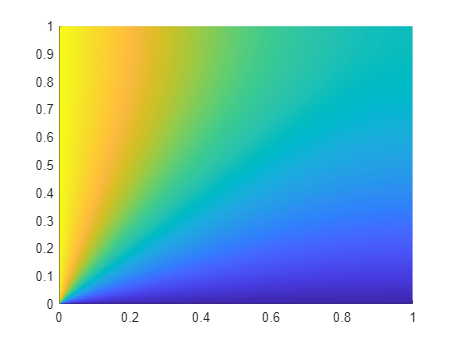

RESULT = outputField(mesh,outputSelect.smooth,T);